clear; 
s0_add_paths;

# Create the image features

nOri = 8; nSurroundOrient = 8;
nCentOrient = 2;
orientations = linspace(0, pi, nOri+1);
orientations = orientations(1:end-1) - (pi/2);
surrOrient = orientations;
centOrient  = deg2rad([0 22.5]); 

numpix  = 450;
pixperdeg = 75;
filter_cpd = 3;
ppc     = round(pixperdeg./ filter_cpd); % pixels per cycle
support = 6;
padsize = ppc .* support; 

num     = numpix; % number of pixels in 2 cycles
surroundSize = round(pixperdeg * 5);
centerSize = round(pixperdeg * 2);
picMask = gen_disk(num, surroundSize, 1);
cenMask = gen_disk(num, centerSize, 1);


### The stimuli with surround suprresion

Images vary across 8 surround orientations and 4 center orientations

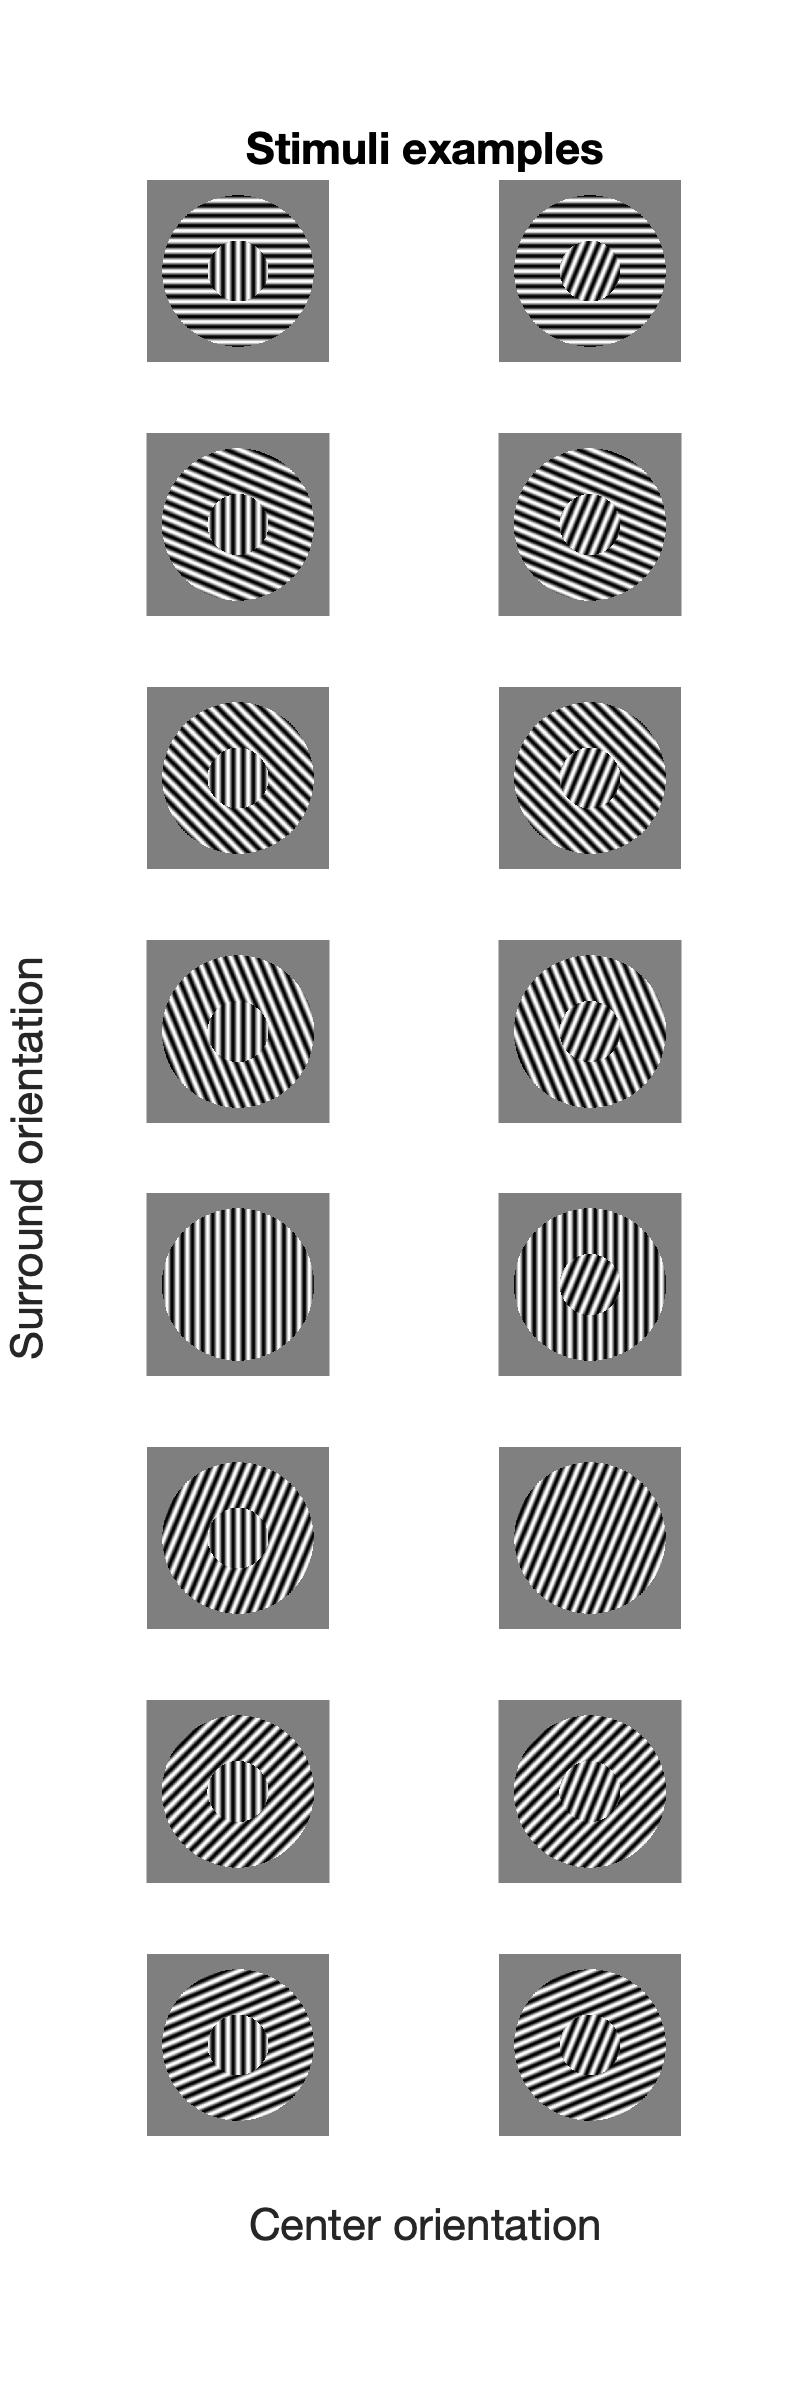

tune_stim = cell(nCentOrient, 1);
surr_stim = cell(nSurroundOrient, nCentOrient);
[x, y]  = meshgrid((0:num- 1)/ppc);

for i = 1:nSurroundOrient
    for j = 1:nCentOrient
        % Center
        theta = centOrient(j);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        center = 0.5*(cenMask.*real(h));
        
        % Surround
        theta = surrOrient(i);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        h = real(h);
        surr = 0.5*(picMask.*h.*(1-cenMask));
        
        surr_stim{i, j} = surr + center;
        
    end
end

fig = figure('Renderer', 'painters', 'Position', [10 10 200*nCentOrient 1200]);
for i = 1:nCentOrient 
    for j = 1:nSurroundOrient
        subplot(nSurroundOrient, nCentOrient, (j-1)*nCentOrient+i)
        imshow(surr_stim{j, i}, [])
        n = size(surr_stim{j, i}, 1);
%         title(sprintf('%d x %d', n, n))
    end
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel(han,'Center orientation');
ylabel(han,'Surround orientation');
title(han,'Stimuli examples');

## Stimuli used to create tuning curve

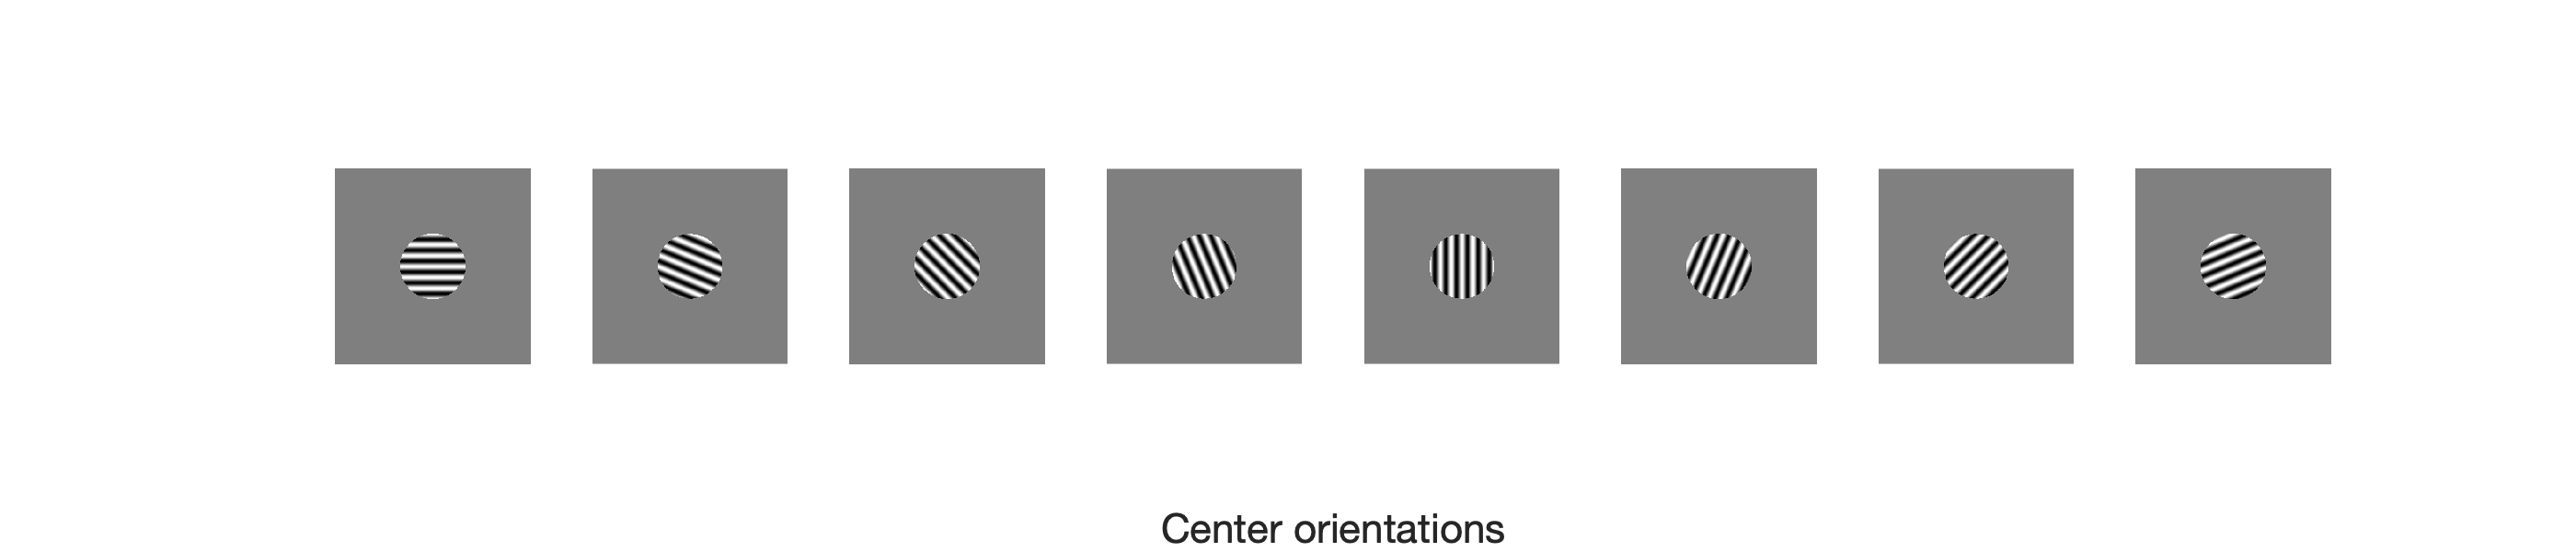

tune_stim = cell(nCentOrient, 1);
for i = 1:nOri
    [x, y]  = meshgrid((0:num- 1)/ppc);
    theta = orientations(i);
    wave_c = cos(theta);
    wave_s = sin(theta);
    h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
    tune_stim{i,1} = .5*(cenMask.*real(h));
end

fig = figure('Renderer', 'painters', 'Position', [10 1200 1400 300]);
for i = 1:nOri
    subplot(1, nOri, i)
    imshow(tune_stim{i, 1}, [])
    n = size(tune_stim{i, 1}, 1);
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.XLabel.Visible='on';
xlabel(han,'Center orientations');

# Frame the problem

### Energy extraction

#### 
$$E(x,y,\theta) = \sum_{\phi}\left(I(x, y)F(x,y,\theta, \phi)\right)^2$$


#### * $I$ the image

#### * $F$ the filter (the neuron)

#### * $x,\;y$ indicates the neuron's location

#### * $x^{\prime } ,y^{\prime } \;$is the neuron's receptive field

#### * $\theta \;$ neuron's preferred orientation

#### * $\phi \;$ the phases, sine or cosine

### Get the filters (Neurons)

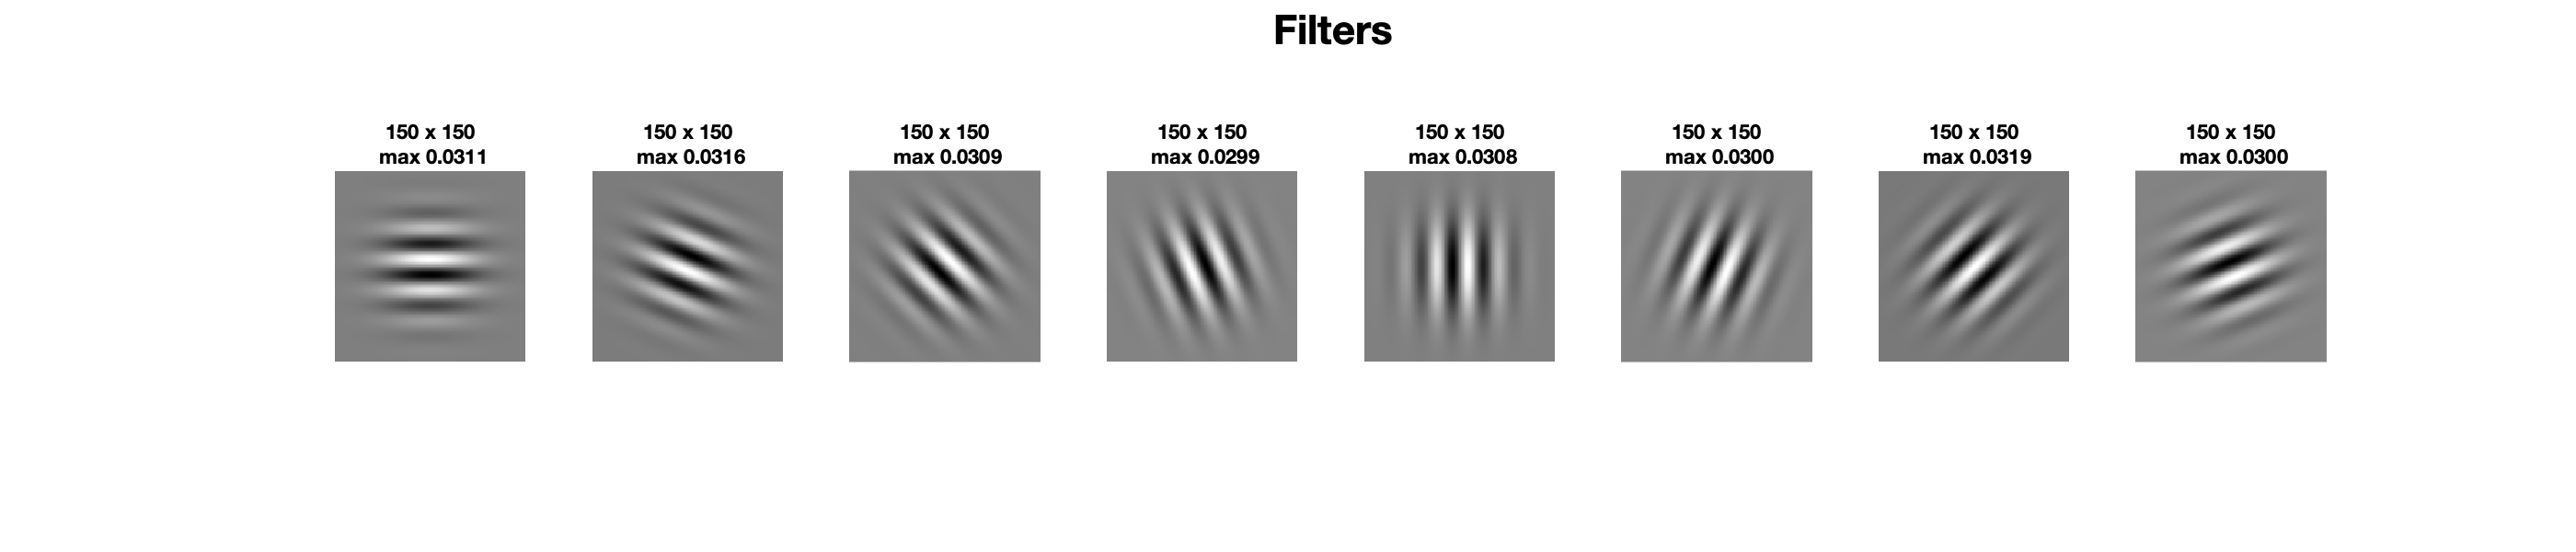

% extract contrast energy
% create filters
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 300]);
[Gabor_c, Gabor_s] = makeGaborFilter(ppc, orientations, support);
for i = 1:nOri
    subplot(1, nOri, i)
    imshow(Gabor_c{i}, [])
    n = size(Gabor_c{i}, 1);
    title(sprintf('%d x %d\n max %.04f', n, n, max(Gabor_c{i}(:))))
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.Title.Visible='on';
title(han,'Filters');

### Extract the contrast energy 

% x, y, orient_channnel, surrOri, centOri
tune_E = nan(numpix, numpix, nOri, nOri);
surr_E = nan(numpix, numpix, nOri, nSurroundOrient, nCentOrient);

for i = 1:nOri
    
    tune_E(:, :, :, i) = Icontrast(tune_stim{i, 1}, Gabor_c, Gabor_s);

    for j = 1:nCentOrient
        surr_E(:, :, :, i, j) = Icontrast(surr_stim{i, j}, Gabor_c, Gabor_s);
    end
end

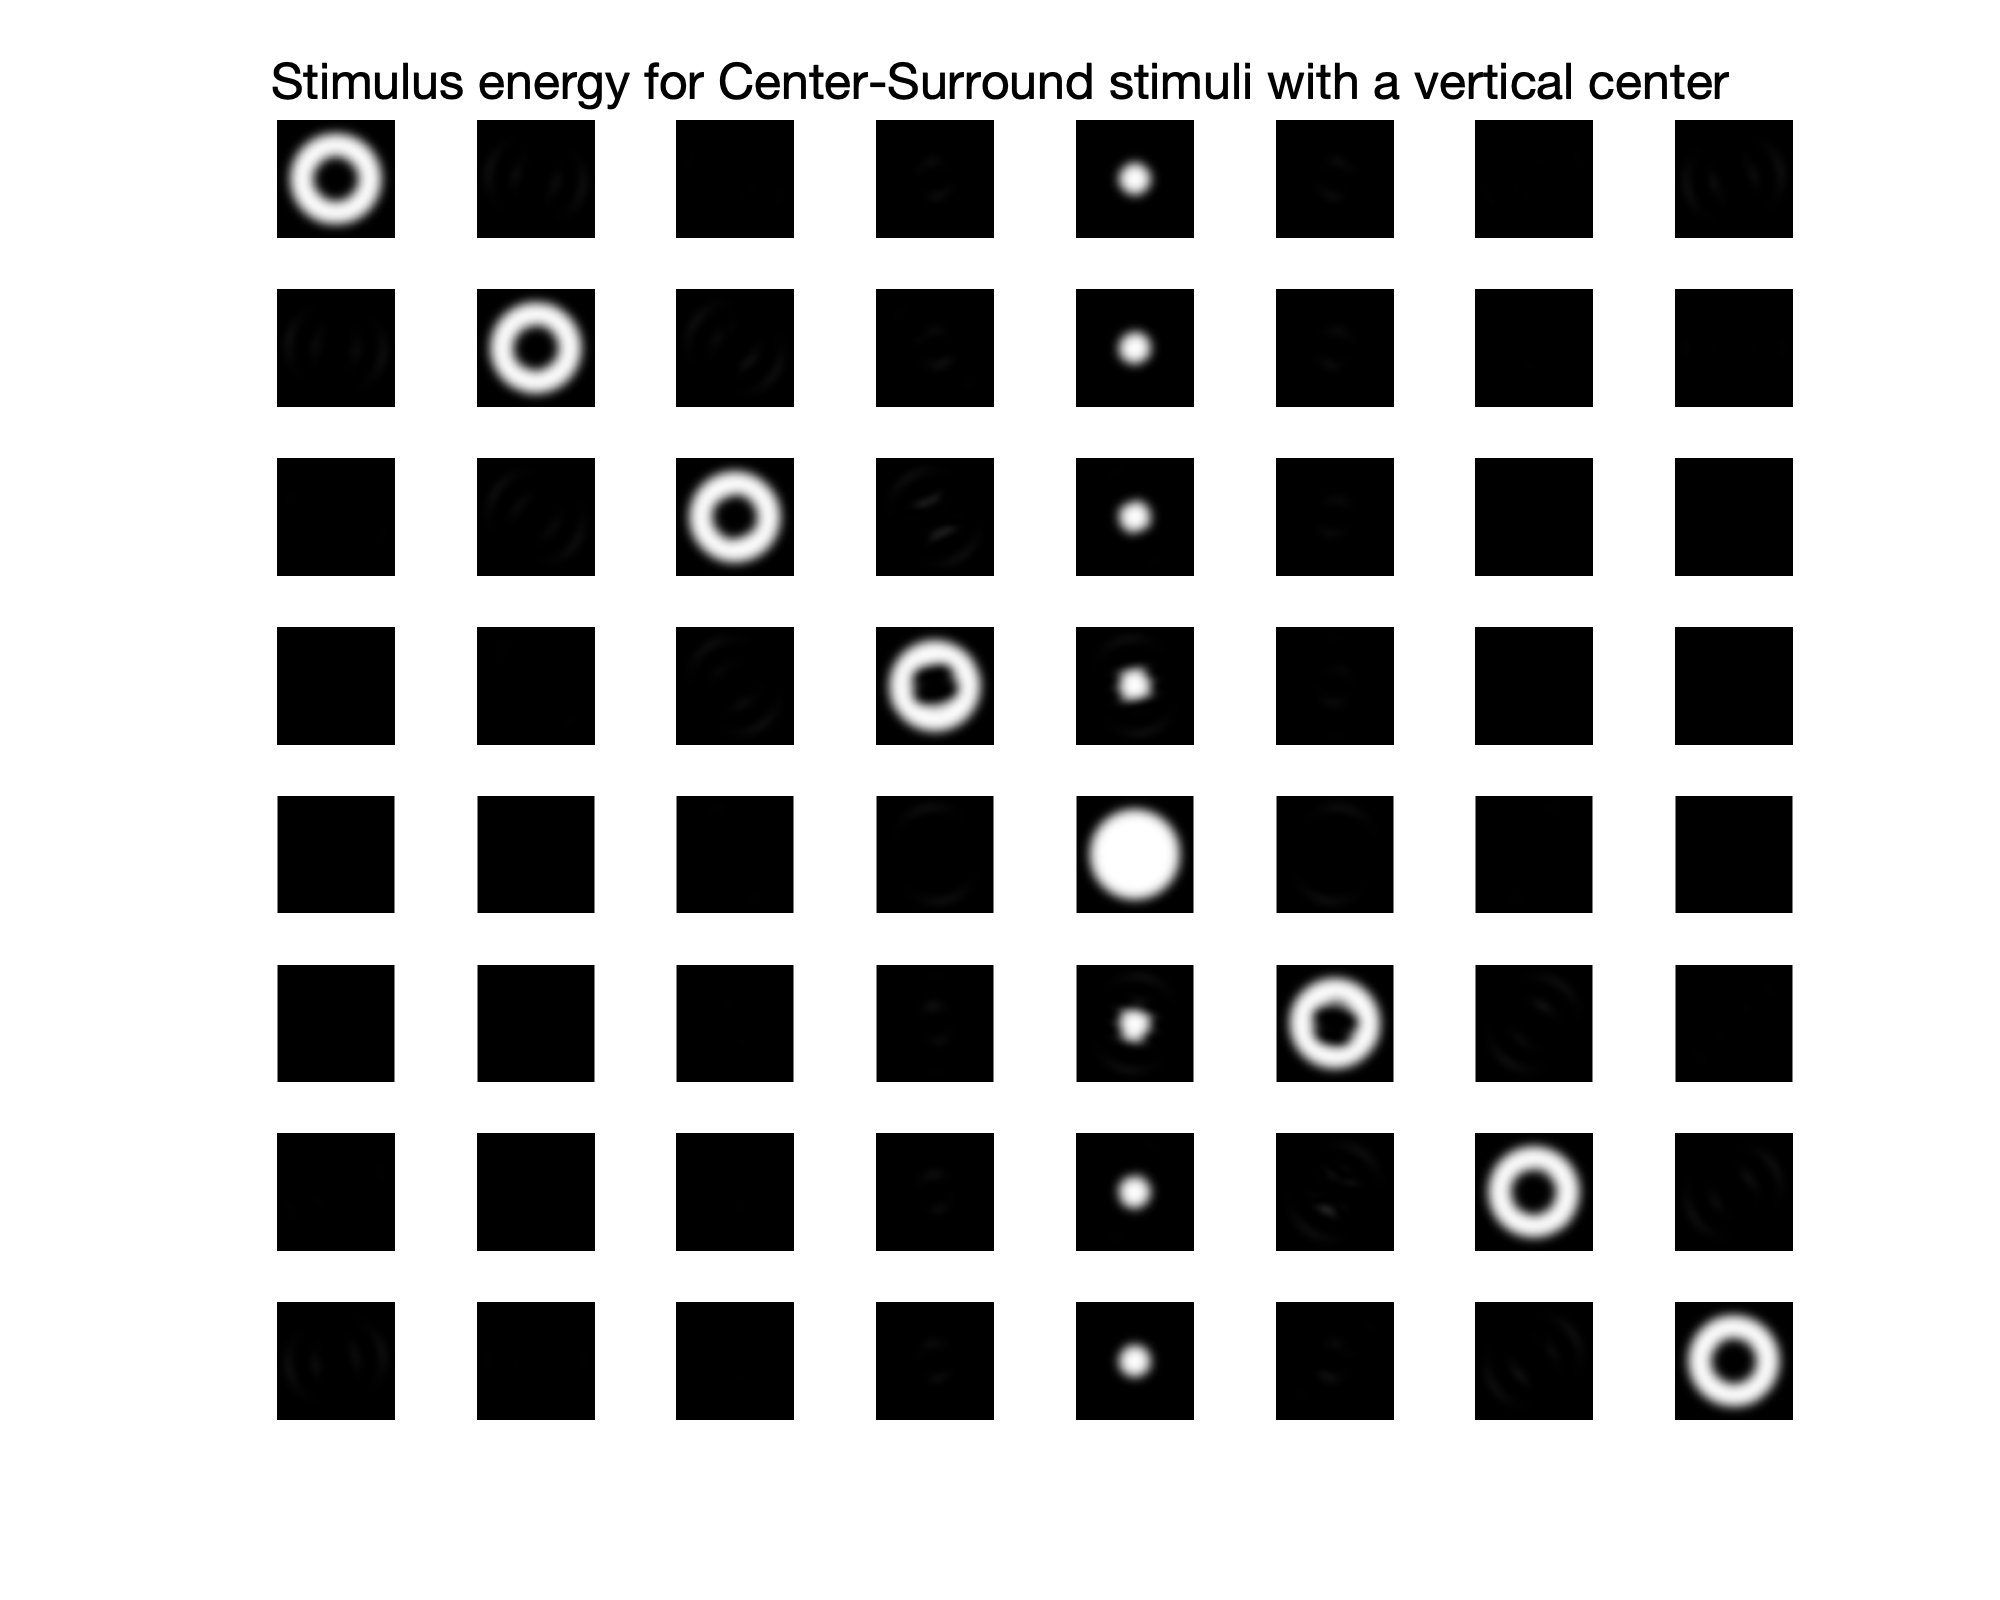

fig = figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
surr_E1 = surr_E(:, :, :, :, :);
maxe = max(surr_E1(:));
mine = min(surr_E1(:));
for j = 1:nSurroundOrient
    for i = 1:nOri
        subplot(nSurroundOrient, nOri, nOri*(j-1)+i)
        tar = surr_E(:,:,i,j,1);
        imshow(tar, [0, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
xlabel(han,'Filter orientations','FontSize', 20);
ylabel(han,'Surround orientations','FontSize', 20);
sgtitle('Stimulus energy for Center-Surround stimuli with a vertical center', 'FontSize', 25)

# Calculate the neurons' response at the center 

### The general equation that calculate the response is 

#### 
$$d(\theta^c) = \sum_{x,y\in C} \frac{E(x, y, \theta^c)}{\sigma + Z(x,y,\theta^c)}$$


* $Z$ is the normalization

* $C$ is the center area, see the below figure. 

* $\theta^c$ preferred orientation for neurons at the center

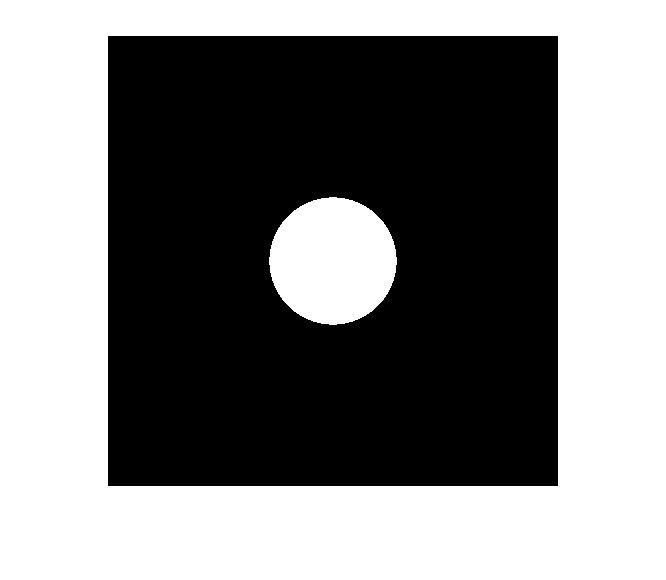

% the center mask: C
figure;
w = gen_disk(numpix, centerSize);
imshow(w, [])

### The CE model 

The model postulates that the normalization is a constant


$$Z = \text{Const}$$


#### A example 

% example for CE model
neuronTuning = 5;
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(surr_E(:,:,:,:,:));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));

% d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Filter orient x surround orient x center orient
r_surrCE = squeeze(s(neuronTuning,:,:)); 


params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,neuronTuning));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (Z + sig);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));
% add exponential
s = d.^alpha;
r_centCE = s; 

#### Get the curves

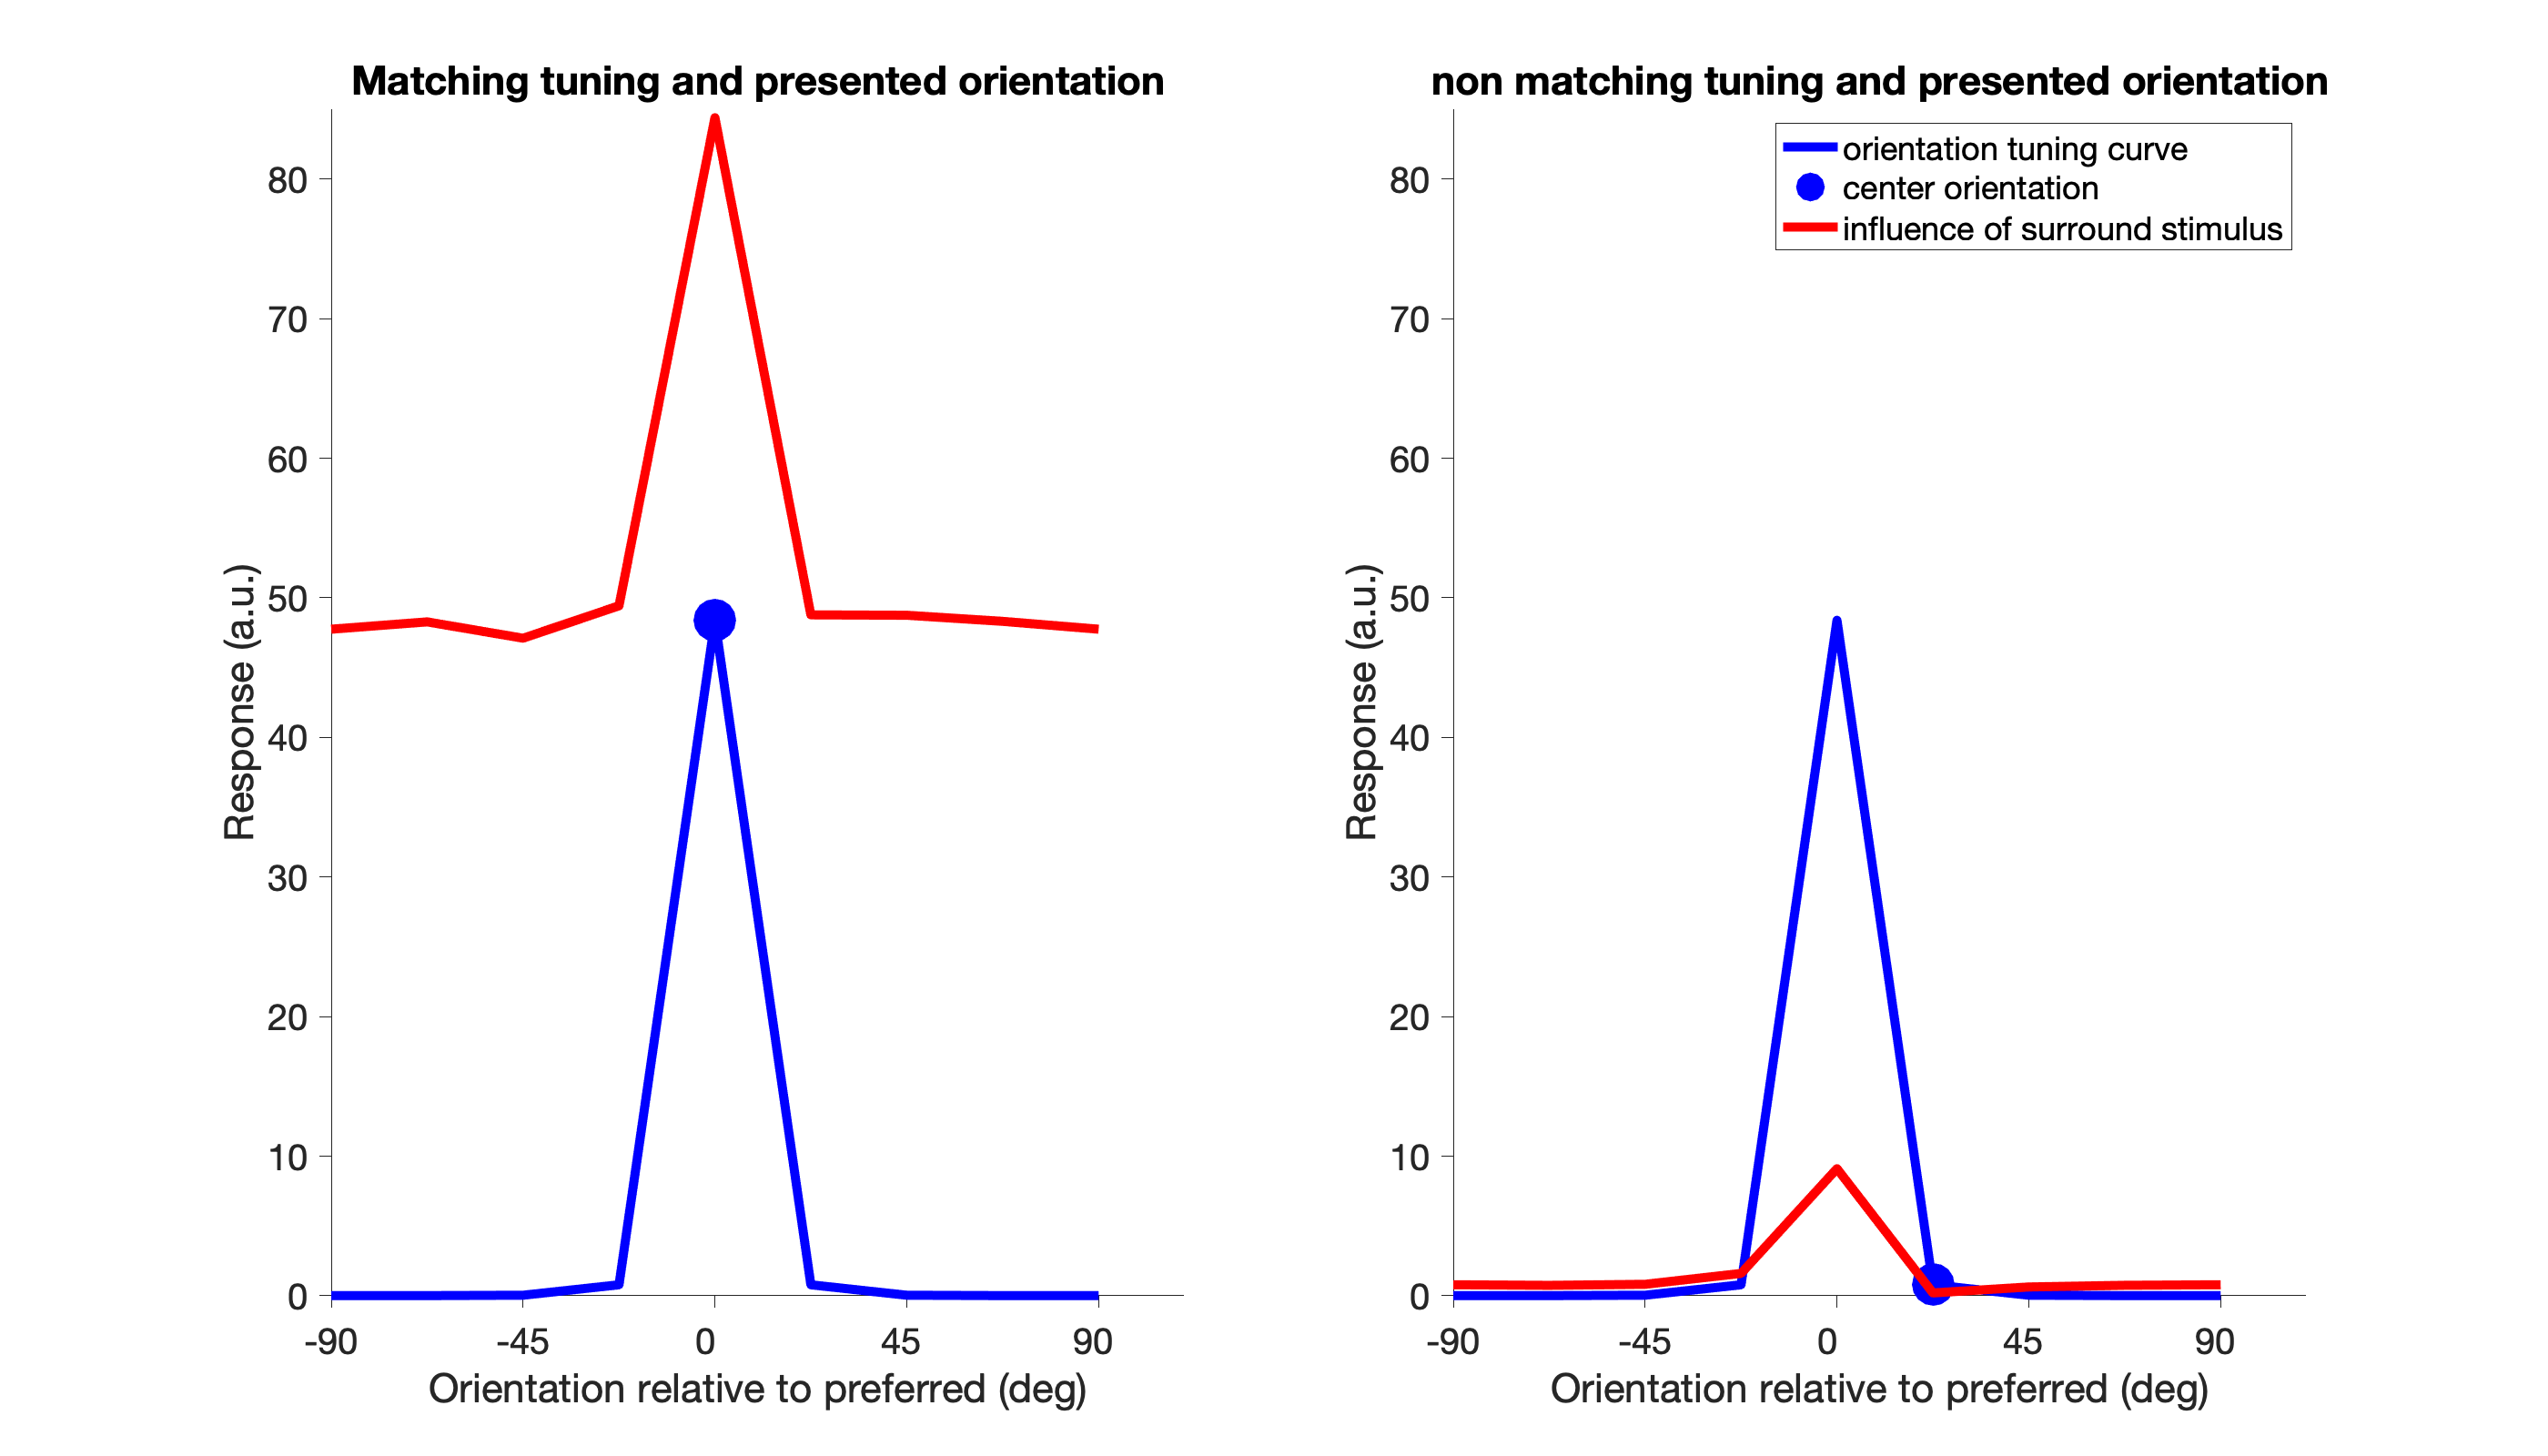


tune_curve1 = [r_centCE; r_centCE(1)];
supp_curve1 = [r_surrCE; r_surrCE(1,:)];

ybounds = [0 ceil(max(supp_curve1(:)))];
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800]);
subplot(1,2,1)
plot(0:22.5:180, tune_curve1, 'b', 'LineWidth', 5)
hold on
plot(90, tune_curve1(5), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve1(:,1),'r', 'LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation')


subplot(1,2,2)
plot(0:22.5:180, tune_curve1,'b','LineWidth', 5)
hold on
plot(112.5, tune_curve1(6), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve1(:,2),'r','LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation')
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus')

han=axes(fig,'visible','off');
title(han,'Dependence of surround suppression on center orientation','FontSize', 20);

### The OTS model 

The model postulates that the normalization is a constant


$$Z(\theta) = \sum_{x',y',\theta'} E(x', y', \theta)F(x', y', \theta';\theta)$$


#### A example 

% Compute tuned normalization pool
neuronTuning = 5;

sig_long  = .8;
sig_short  = .8;
sig_dot = .01;

sz = round(size(surr_E, 1) / 10)*2;

F = kernel_weight(sig_long, sig_short, sig_dot, sz, 'oriTuned');
r_surround = NaN(nOri,nCentOrient);

for whichCent = 1:nCentOrient
    
    Z = NaN(size(surr_E,1), size(surr_E,2), size(surr_E,3), size(surr_E,4));

    for ep = 1:nSurroundOrient
        % energy: x, y, neuron orient, center Orient, Surround orient
        E = surr_E(:, :, :, ep, whichCent);
    
        Z_thetas = NaN(size(E));
        
        for theta1 = 1:nOri
            Ztheta1 = 0;
            for theta2 = 1:nOri
                kernel_2d = F(:,:,theta1,theta2);
                image_theta = E(:,:,theta2);
                z_theta = conv2(image_theta, kernel_2d, 'same');
                Ztheta1 = Ztheta1 + z_theta;
            end
            Z_thetas(:,:,theta1) = Ztheta1;
        end
        
        Z(:,:,:,ep) = Z_thetas;
    end


    % Normalize stimulus energy
    params = [.1, 1];
    sig = params(1); alpha = params(2);
    
    % normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
    D = squeeze(surr_E(:,:,:,:,whichCent)) ./ (sig + Z(:,:,:,:));
    
    % sum over the response at center, and select the target orientation
    % d = ∑_(x, y in C) D(x,y,θ*)
    d = squeeze(mean(w .* D, [1, 2]));
    % add exponential
    s = d.^alpha;
    % Response tuned for one center orientation influenced by different surround
    % orientations
    r_surround(:,whichCent) = s(neuronTuning,:);
 
end

## Normalized center responses

neuronTuning = 5;
% X x Y x Orient x SurroundDiff
Z = NaN(size(tune_E,1), size(tune_E,2), size(tune_E,3), size(tune_E,4));
for ep = 1:nOri
    % energy: x, y, neuron orient, center Orient
    E = tune_E(:, :, :, ep);

    Z_thetas = NaN(size(E));
    
    for theta1 = 1:nOri
        Ztheta1 = 0;
        for theta2 = 1:nOri
            kernel_2d = F(:,:,theta1,theta2);
            image_theta = E(:,:,theta2);
            z_theta = conv2(image_theta, kernel_2d, 'same');
            Ztheta1 = Ztheta1 + z_theta;
        end
        Z_thetas(:,:,theta1) = Ztheta1;
    end
    
    Z(:,:,:,ep) = Z_thetas;
end

% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = squeeze(tune_E(:,:,:,:)) ./ (sig + Z);

% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Response to all center orientations for a neuron tuned to whichCent
r_center = s(:,neuronTuning);
 


#### Get the curves

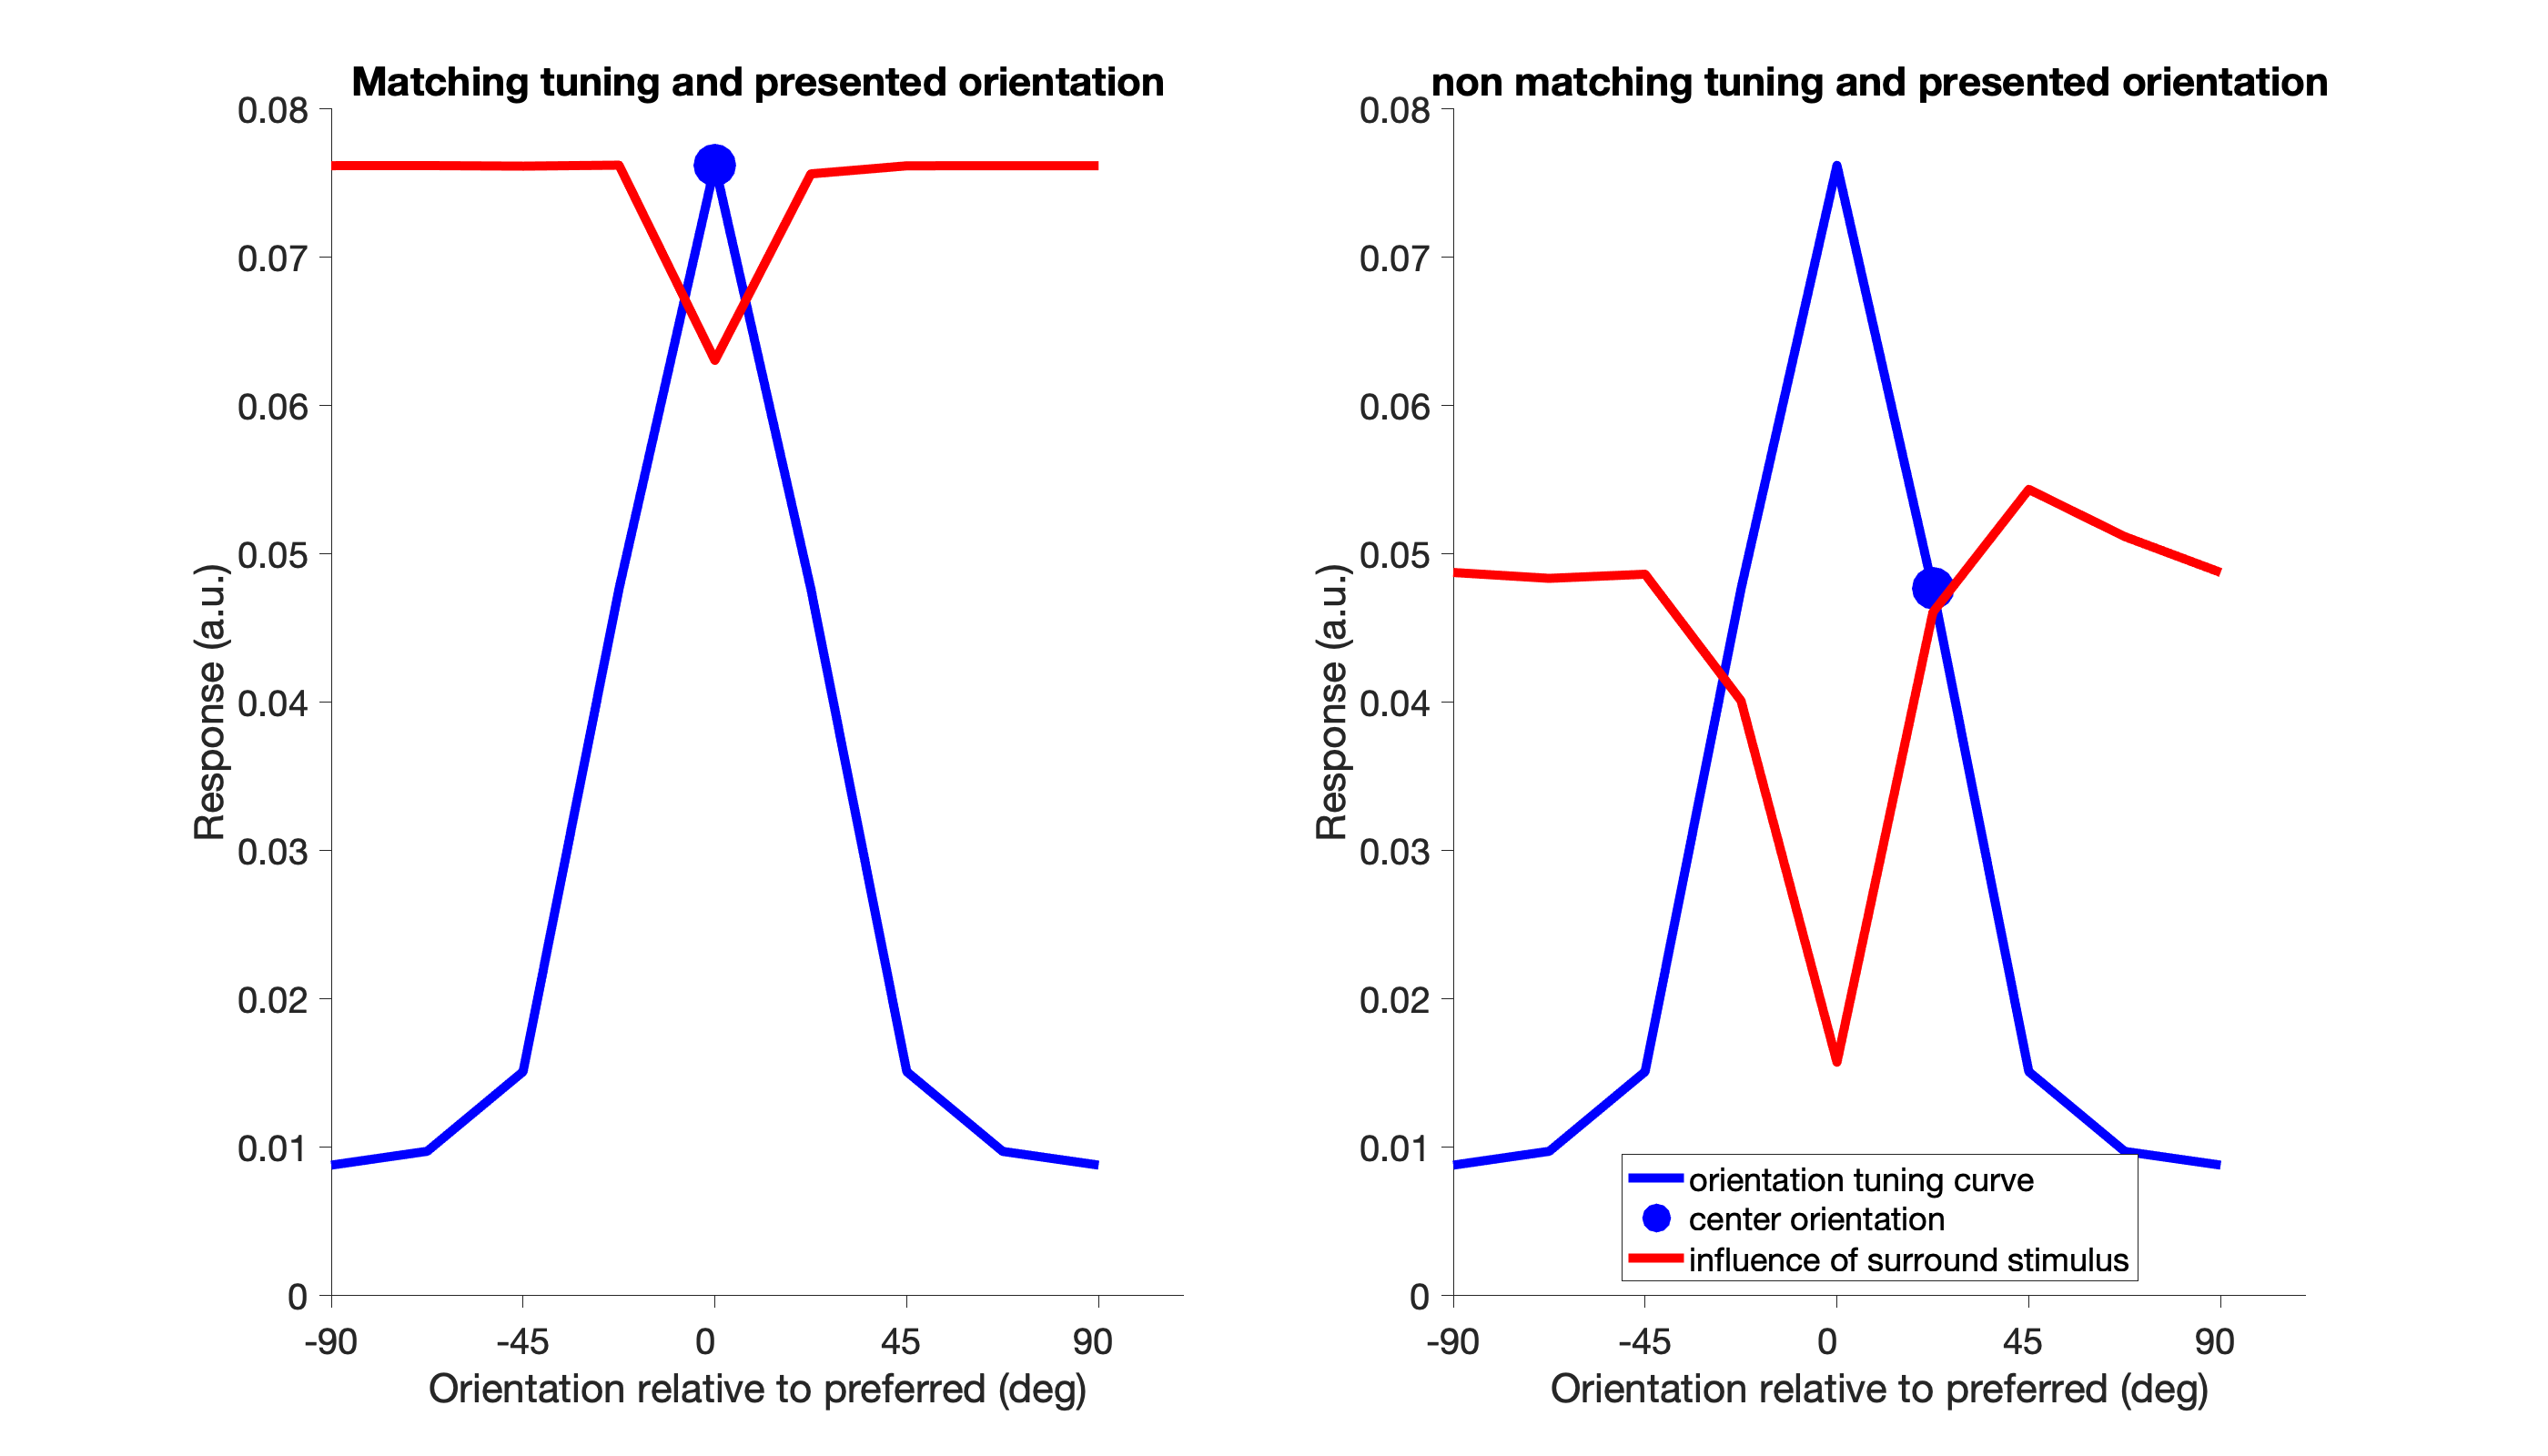


tune_curve2 = [r_center; r_center(1)];
supp_curve2 = [r_surround; r_surround(1,:)];

ybounds = [0 ceil(max(supp_curve2(:)*100))/100];
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800]);
subplot(1,2,1)
plot(0:22.5:180, tune_curve2, 'b', 'LineWidth', 5)
hold on
plot(90, tune_curve2(5), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve2(:,1),'r', 'LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation')


subplot(1,2,2)
plot(0:22.5:180, tune_curve2,'b','LineWidth', 5)
hold on
plot(112.5, tune_curve2(6), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve2(:,2),'r','LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation')
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus', 'Location',"south")

han=axes(fig,'visible','off');
title(han,'Dependence of surround suppression on center orientation','FontSize', 20);

% yline(prefer_res, '-.k', 'LineWidth', 3)

#### NOA model

% example for NOA model
neuronTuning = 5;

params = [.1, 1];
sig = params(1); alpha = params(2);
r_surrNOA = NaN(nOri, nCentOrient);

for whichCent = 1:nCentOrient
    % energy: % x, y, orient_channnel, surrOri, centOri
    E = squeeze(surr_E(:,:,:,:,whichCent));
    % get normalizer: Z = const 
    E_ori = squeeze(mean(E .* w, [1, 2]));
    Z = std(E_ori, 1);
    % normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
    d = E_ori ./ (sig + Z);
    % add exponential
    s = d.^alpha;
    % Filter orient x surround orient
    r_surrNOA(:,whichCent) = s(neuronTuning,:); 
end


% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,neuronTuning));
% get normalizer: Z = const
E_ori = squeeze(mean(E .* w, [1, 2]));
Z = std(E_ori, 1);
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
d = E_ori ./ (sig + Z);
% add exponential
s = d.^alpha;
r_centNOA = s; 

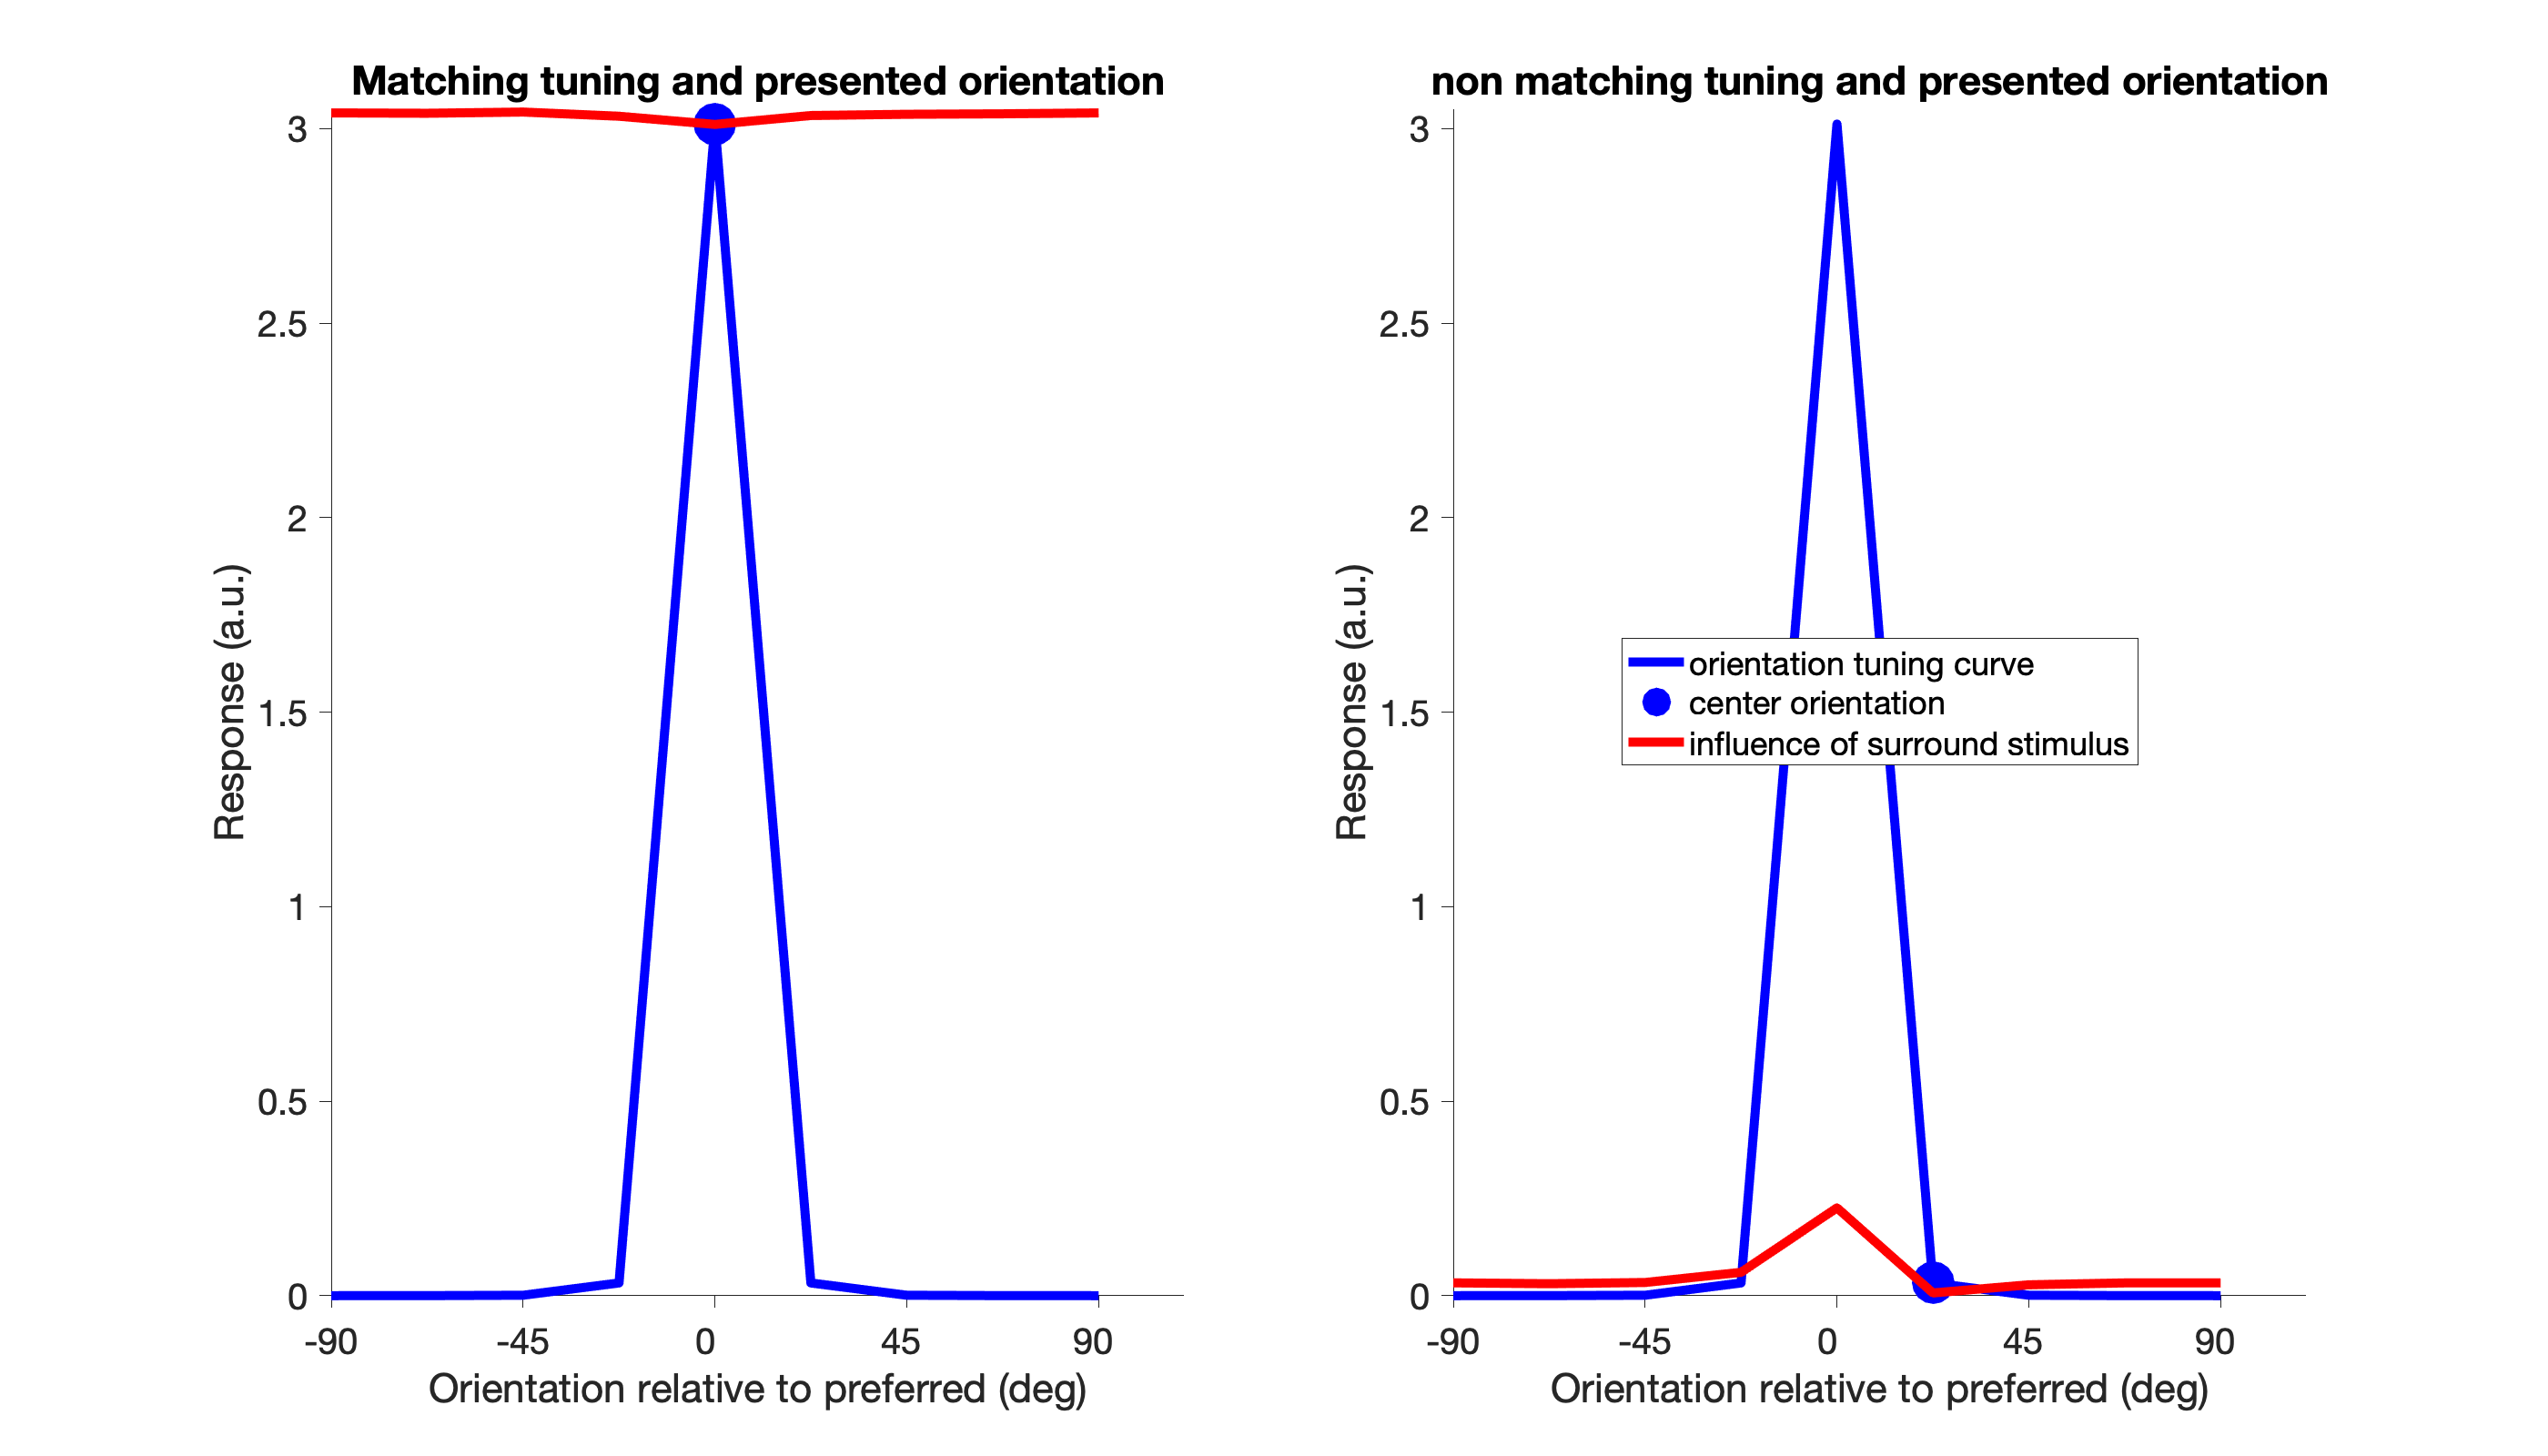

%
tune_curve3 = [r_centNOA; r_centNOA(1)];
supp_curve3 = [r_surrNOA; r_surrNOA(1,:)];

ybounds = [0 ceil(max(supp_curve3(:)*100))/100];
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800]);
subplot(1,2,1)
plot(0:22.5:180, tune_curve3, 'b', 'LineWidth', 5)
hold on
plot(90, tune_curve3(5), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve3(:,1),'r', 'LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation')


subplot(1,2,2)
plot(0:22.5:180, tune_curve3,'b','LineWidth', 5)
hold on
plot(112.5, tune_curve3(6), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve3(:,2),'r','LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation')
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus', 'Location',"Best")

han=axes(fig,'visible','off');
title(han,'Dependence of surround suppression on center orientation','FontSize', 20);